# Radar Signal Processing Verification

This script has been written to confirm that the signal processing component of a radar is working as anticipated

## Initialize the simulator

clear;
simulator = Simulator_revB();
% file_path = "/home/david/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/B210_params.json";
% file_path = "/home/david/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/B210_params_highBW.json";
% file_path = "/home/david/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/B210_params_highvres.json";
% file_path = "/home/david/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/B210_params_lowBW.json";
% file_path = "/home/david/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/B210_params_sensing_system.json";
% file_path = "/home/david/Documents/RadarSecurityResearch/MATLAB/Simulink Model/config_files/X310_params_100MHzBW.json";
file_path = "C:\Users\krist\OneDrive\Documents\2022-2023 School Year\Radar Security Project\RadarSecurityResearch\MATLAB\Simulink Model\config_files\realistic_params.json";
simulator.load_params_from_JSON(file_path);

%apply timing offsets as desired
simulator.Victim.timing_offset_us = 0;
simulator.Attacker.Subsystem_tracking.timing_offset_us = 0;

%configure the FMCW parameters
simulator.configure_FMCW_Radar_parameters();

%load default attacker, and victim positions and velocities
simulator.load_realistic_attacker_and_victim_position_and_velocity();

%print out key parameters
simulator.Victim.print_chirp_parameters;

Chirp Parameters
	 Start Frequency: 		 77.00 GHz
	 Frequency Slope: 		 10.76 MHz/us
	 Idle Time: 			 7.95 us
	 Tx Start Time: 		 0.00 us
	 ADC Valid Start Time: 		 6.42 us
	 ADC Samples: 			 256 
	 ADC Sample Rate: 		 7.17 MSps
	 Ramp End Time: 		 42.12 us
	 Chirp Tx Bandwidth: 		 453.21 MHz
	 Chirp Sampling Bandwidth: 	 384.18 MHz
	 ADC Sampling Period: 		 35.70 us
	 Chirp Cycle Time: 		 50.07 us
	 Chirp Wavelength: 		 3.89 mm



simulator.Victim.print_frame_parameters;

Frame Parameters
	 Number of Chirps 		 128
	 FramePeriodicity 		 33.35 ms
	 Active Frame Time 		 6.41 ms


%log detection first, then log all the data about it
simulator.Victim.print_performance_specs;

Performance Specifications
	 Max Range 			 99.88 m
	 Range Resolution 		 0.39 m
	 Max Velocity 			 19.44 m/s
	 Velocity Resolution 		 0.30 m/s


simulator.Victim.print_FMCW_specs;

FMCW Specifications
	 FMCW sampling rate 		 458.88 MHz
	 Downsampling factor 		 64
	 Sweep time 			 42.12 us
	 Samples per chirp 		 22976.00 


## Initialize the Target

simulator.load_target_realistic(10, 185);

## Run the simulation

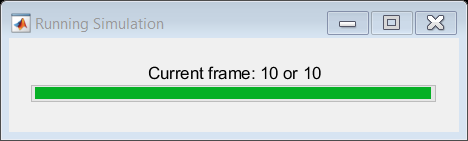

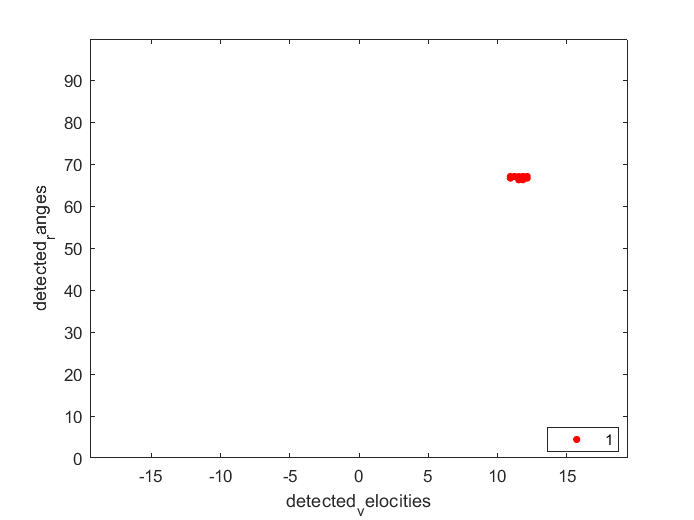

%specify the number of frames and chirps to compute
frames_to_compute = 10;

%specify whether or not to record a move of the range-doppler plot
record_movie = true;
simulator.Victim.Radar_Signal_Processor.configure_movie_capture(frames_to_compute,record_movie);

%pre-compute the victim's chirps
simulator.Victim.precompute_radar_chirps();

%run the simulation (without an attacker for now)
simulator.run_simulation_no_attack(frames_to_compute);

## Results

% determine if an object has been detected in each frame
detected = performance_functions.detection(frames_to_compute, simulator.Victim.Radar_Signal_Processor.range_estimates)

detected =      1     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0
     1     0     0     0     0     0     0     0     0     0


% report the range estimates
estimated_ranges = simulator.Victim.Radar_Signal_Processor.range_estimates

estimated_ranges =    11.8913       NaN       NaN       NaN       NaN
   17.9901       NaN       NaN       NaN       NaN
   24.1116       NaN       NaN       NaN       NaN
   30.1957       NaN       NaN       NaN       NaN
   36.3046       NaN       NaN       NaN       NaN
   42.4206       NaN       NaN       NaN       NaN
   48.4990       NaN       NaN       NaN       NaN
   54.6196       NaN       NaN       NaN       NaN
   60.7288       NaN       NaN       NaN       NaN
   66.8068       NaN       NaN       NaN       NaN


% compute the actual range per frame
actual_ranges = performance_functions.actual_ranges(frames_to_compute, simulator.Victim.FramePeriodicity_ms*.001, simulator.SimulatedTarget.velocity_meters_per_s, simulator.Victim.velocity_m_per_s, simulator.SimulatedTarget.position_m, simulator.Victim.position_m)

actual_ranges =    10.0000   18.2693   28.1241   38.3615   48.7409   59.1877   69.6716   80.1780   90.6991  101.2303


% compute the percent error of the range estimate for each frame
percent_error_ranges = performance_functions.range_percent_error(actual_ranges, estimated_ranges)

percent_error_ranges =     1.8913
    0.2792
    4.0125
    8.1658
   12.4363
   16.7671
   21.1726
   25.5584
   29.9703
   34.4235


% report the velocity estimates
estimated_velocities = simulator.Victim.Radar_Signal_Processor.velocity_estimates

estimated_velocities =    11.8125       NaN       NaN       NaN       NaN
   11.8145       NaN       NaN       NaN       NaN
   11.8165       NaN       NaN       NaN       NaN
   11.8207       NaN       NaN       NaN       NaN
   11.8180       NaN       NaN       NaN       NaN
   11.8151       NaN       NaN       NaN       NaN
   11.8279       NaN       NaN       NaN       NaN
   11.8234       NaN       NaN       NaN       NaN
   11.8188       NaN       NaN       NaN       NaN
   11.8333       NaN       NaN       NaN       NaN


% compute the actual velocity per frame
actual_velocities = performance_functions.actual_velocities(frames_to_compute, simulator.SimulatedTarget.velocity_meters_per_s, simulator.Victim.velocity_m_per_s)

actual_velocities =   -183  -183  -183  -183  -183  -183  -183  -183  -183  -183


% compute the velocity percent error per frame
percent_error_velocities = performance_functions.velocity_percent_error(estimated_velocities, actual_velocities)

percent_error_velocities =   194.8125
  194.8145
  194.8165
  194.8207
  194.8180
  194.8151
  194.8279
  194.8234
  194.8188
  194.8333


%play the movie for the range doppler
if record_movie
    simulator.Victim.Radar_Signal_Processor.play_range_doppler_movie();
end

%play the movie for the clusters
if record_movie
    simulator.Victim.Radar_Signal_Processor.play_clustering_movie()
end